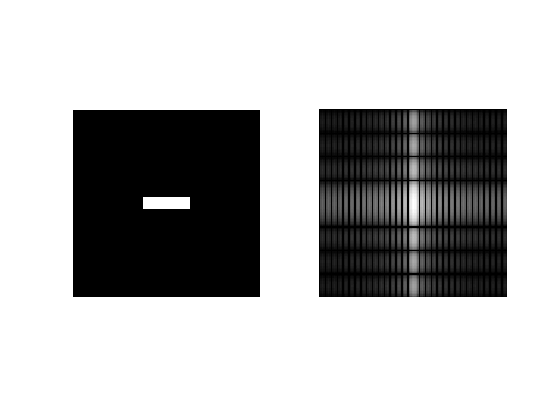

F=[zeros(60,128); ones(8,128); zeros(60,128)].*... 
    [zeros(128,48) ones(128,32) zeros(128,48)];
subplot(1,2,1)
showgrey(F);
subplot(1,2,2)
showfs(fft2(F));

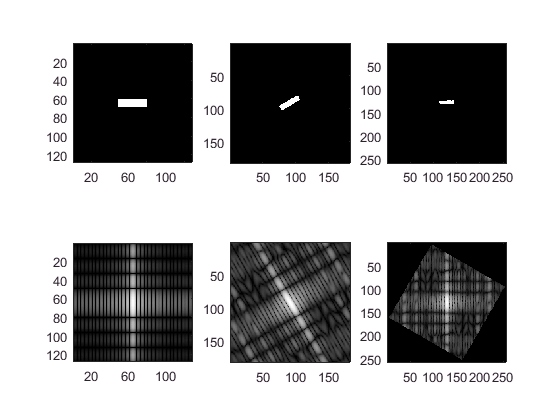


figure

subplot(2,3,1)
showgrey(F);
axis on
subplot(2,3,4)
showfs(fft2(F));
axis on

alpha=30;

subplot(2,3,2)
G=rot(F,alpha);
showgrey(G);
axis on
subplot(2,3,5)
Ghat=fft2(G);
showfs(Ghat);
axis on

subplot(2,3,3)
H=rot(G,-alpha);
showgrey(H)
axis on
Hhat=rot(fftshift(Ghat),-alpha);
subplot(2,3,6)
showgrey(log(1+abs(Hhat)))
axis on